# Test met functies


toy_samples = 250;
nb_inputs = 2;
nb_outputs = 2;

sampling_points = randn(nb_inputs, toy_samples);

Jac = zeros(nb_outputs, nb_inputs, toy_samples);
F = zeros(nb_outputs, toy_samples);
for i=1:toy_samples
    point = dlarray(sampling_points(:,i)');
    [F(1,i), Jac(1,:,i)] = dlfeval(@f1, point);
    [F(2,i), Jac(2,:,i)] = dlfeval(@f2, point);
    %[F(3,i), Jac(3,:,i)] = dlfeval(@f3, point);
end

## Test met neuraal netwerk [ 2 2 3 2 2]


toy_samples = 100;
nb_inputs = 2;
nb_outputs = 2;

sampling_points = randn(nb_inputs, toy_samples);

Jac = zeros(nb_outputs, nb_inputs, toy_samples);
F = zeros(nb_outputs, toy_samples);
for i=1:toy_samples
    point = dlarray(sampling_points(:,i)');
    [F(:,i), Jac(:,:,i)] = dlfeval(@all_layers, point);
end

## Algoritme oproep

warning("off")

bf1 = {@theta1, @theta2, @theta3, @theta4, @theta5, @theta6, @theta7};
bf2 = {@theta1, @theta2, @theta3, @theta4, @theta5, @theta6, @theta7};

r1 = 3;
r2 = 2;

[We, D2e, Vte, D1e, Zte, Ht, cD1e, cD2e] = PARATUCK2_CMTF(Jac, F, bf1, bf2, r1, r2, sampling_points);

error = 1.4287e-07

error = 1.4287e-07

## Vergelijking met functies

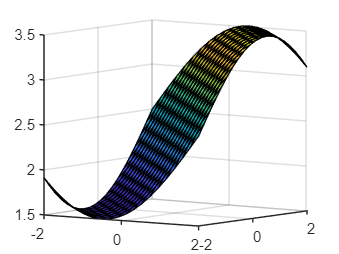

x = linspace(-2,2,20);
y = x';
z = zeros(20);
zb = zeros(20,20,nb_outputs);
for i=1:20
    for j=1:20
        point = dlarray([x(i), y(j)]);
        [z(i,j), ~] = dlfeval(@f1, point);
        zb(i,j,:) = fbar([x(i); y(j)], We, Vte, Zte, cD1e, cD2e, r1, r2);
    end
end

% Origineel
surf(x,y,z)
view([35.05 6.20])

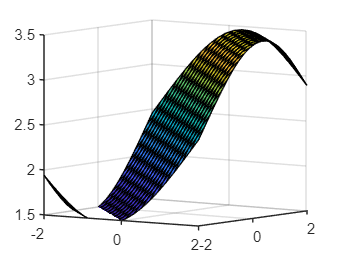

% Benadering
surf(x,y,zb(:,:,1))
view([35.05 6.20])
zlim([1.5 3.5])

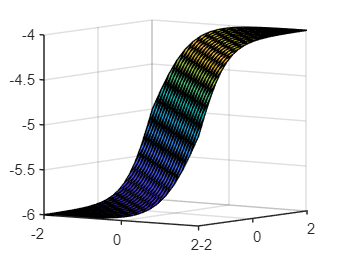



z = zeros(20);
for i=1:20
    for j=1:20
        point = dlarray([x(i), y(j)]);
        [z(i,j), ~] = dlfeval(@f2, point);
    end
end

% Origineel
surf(x,y,z)
view([35.05 6.20])

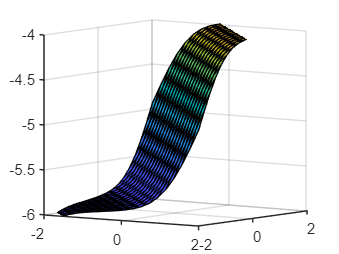

% Benadering
surf(x,y,zb(:,:,2))
view([35.05 6.20])
zlim([-6 -4])

## Vergelijking met netwerk

u = dlarray([0.1 0.3])

u =   1×2 dlarray

    0.1000    0.3000


[result, ~] = dlfeval(@all_layers, u);
result

result =    -0.2630
    1.1151



apprResult = fbar(u', We, Vte, Zte, cD1e, cD2e, r1, r2);
apprResult

apprResult =    -0.2630
    1.1152




u = dlarray([0.5 0.5])

u =   1×2 dlarray

    0.5000    0.5000


[result, ~] = dlfeval(@all_layers, u);
result

result =    -0.2636
    1.1176



apprResult = fbar(u', We, Vte, Zte, cD1e, cD2e, r1, r2);
apprResult

apprResult =    -0.2636
    1.1176




u = dlarray([0.2 0.2])

u =   1×2 dlarray

    0.2000    0.2000


[result, ~] = dlfeval(@all_layers, u);
result

result =    -0.2630
    1.1155



apprResult = fbar(u', We, Vte, Zte, cD1e, cD2e, r1, r2);
apprResult

apprResult =    -0.2630
    1.1155


## Resultaten opslaan

save("SavedVariables/PARATUCK2/Structured/CMTF/PT2_toy_network_3_2_S100_2");

function [f,grad] = f1(x)
    f = 2.5 + sin(0.2 * pi * (x(1) + x(2)));
    grad = dlgradient(f,x);
end

function [f,grad] = f2(x)
    f = -5 + tanh(sum(x));
    grad = dlgradient(f,x);
end

function [f,grad] = f3(x)
    f = cos(sum(x)) - 1;
    grad = dlgradient(f,x);
end

function[f,grad] = all_layers(x)
    W0 = [0.2, 0.4; 0.5, 0.1];
    W1 = [0.02, 0.3; 0.1, 0.4; 0.2, 0.6];
    W3 = [0.4 0.3 0.3; 0.1 0.5 0.2];
    W4 = [-0.7 0.3; 0.5, 1.3];

    interm1 = arrayfun(@sigmoid, W0*x');
    interm2 = arrayfun(@sigmoid, W1 * interm1);
    interm4 = arrayfun(@sigmoid, W3 * interm2);


    f1 = W4(1,:)*interm4;
    f2 = W4(2,:)*interm4;

    f = zeros(2,1);
    f(1) = f1;
    f(2) = f2;
    %f(3) = f3;
    %f(4) = f4;

    grad1 = dlgradient(f1,x);
    grad2 = dlgradient(f2,x);
    %grad3 = dlgradient(f3,x);
    %grad4 = dlgradient(f4,x);

    grad = zeros(2,2);
    grad(1,:) = grad1;
    grad(2,:) = grad2;
    %grad(3,:) = grad3;
    %grad(4,:) = grad4;
end


function [f] = fbar(input, W, Vt, Zt, cD1, cD2, r1, r2)
    P1 = zeros(r1,1);
    x = Zt * input;
    for i=1:r1
        P1(i,1) = cD1((7* (i - 1)) + 1) * x(i) + ...
                 cD1((7* (i - 1)) + 2) * x(i)^2 + ...
                 cD1((7* (i - 1)) + 3) * x(i)^3 + ...
                 cD1((7* (i - 1)) + 4) * x(i)^4 + ...
                 cD1((7* (i - 1)) + 5) * x(i)^5 + ...
                 cD1((7* (i - 1)) + 6) * x(i)^6 + ...
                 cD1((7* (i - 1)) + 7) * x(i)^7;
    end

    P2 = zeros(r2,1);
    x = Vt * P1;
    for i=1:r2
        P2(i,1) = cD2((8* (i - 1)) + 1) + ...
                 cD2((8* (i - 1)) + 2) * x(i) + ...
                 cD2((8* (i - 1)) + 3) * x(i)^2 + ...
                 cD2((8* (i - 1)) + 4) * x(i)^3 + ...
                 cD2((8* (i - 1)) + 5) * x(i)^4 + ...
                 cD2((8* (i - 1)) + 6) * x(i)^5 + ...
                 cD2((8* (i - 1)) + 7) * x(i)^6 + ...
                 cD2((8* (i - 1)) + 8) * x(i)^7;
    end

    f = W * P2;
end


function [f,grad] = theta1(x)
    f = x;
    grad = dlgradient(f,x);
end

function [f,grad] = theta2(x)
    f = x^2;
    grad = dlgradient(f,x);
end

function [f,grad] = theta3(x)
    f = x^3;
    grad = dlgradient(f,x);
end

function [f,grad] = theta4(x)
    f = x^4;
    grad = dlgradient(f,x);
end

function [f,grad] = theta5(x)
    f = x^5;
    grad = dlgradient(f,x);
end

function [f,grad] = theta6(x)
    f = x^6;
    grad = dlgradient(f,x);
end

function [f,grad] = theta7(x)
    f = x^7;
    grad = dlgradient(f,x);
end

function [f,grad] = theta8(x)
    f = x^8;
    grad = dlgradient(f,x);
end

function [f,grad] = theta9(x)
    f = x^9;
    grad = dlgradient(f,x);
end

function [f,grad] = theta10(x)
    f = x^10;
    grad = dlgradient(f,x);
end